#### **Fig 4K & L**

*Author: Yi-Shiou Duh (allenduh@stanford.edu)*

*Date: 3/18/2024*

*FDTD scripts*

    *image_deep_scatters_setup.lsf  -- Setup FDTD environment*

    *image_deep_scatters_run.lsf -- Run FDTD*

    *1800_scatters.mat -- Ramdomly generated scatters*

*This script*

- *Plot field distribution*

- *Focus light using ideal thin lens*

- *Plot the cross section*

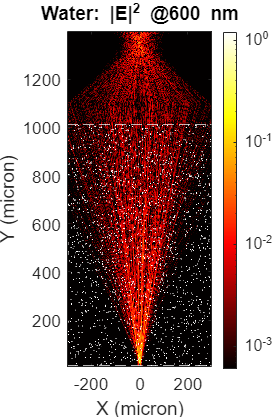

**Load FDTD result**

% Load either water / dye. The file is 3.7 GB large.
clc;clear;

load('image_deep_scatters_03212024_water');   medium = "water";
% load('image_deep_scatters_03262024_dye');     medium = "dye";

mmUnit = 10 ^ -3;
nmUnit = 10 ^ -9; 
umUnit = 10 ^ -6; 
c0 = 299792458;
NA = 0.25; 

**Extract from .mat file**

% Wavelength to plot
wavelengthIndex = 1;   % 1: 600nm, 2: 640nm, 3: 680nm
lambda = fullField_lambda(wavelengthIndex); 
wavelength = lambda / nmUnit;

% X, Y coordinates
xCoordinate = fullField_xCoordinate;
yCoordinate = fullField_yCoordinate;  
ymin = yCoordinate(1);
ymax = yCoordinate (end);

% Particle range
blurry_down_Y = 10; 
blurry_top_Y = 1010; 

% Extract field to plot
Ex_scatter = fullField_Ex(:, :, 1, wavelengthIndex); % (:, :, indexof z = 1, wavelengthIndex from 1 to 3)
Ey_scatter = fullField_Ey(:, :, 1, wavelengthIndex);

E_square = abs(Ex_scatter' .^ 2) + abs(Ey_scatter' .^ 2);
Ex_Before_lens = Ex_scatter(:, end);
%clear("fullField_Ex", "fullField_Ey", "Ex_scatter", "Ey_scatter");

**Plot field distribution**

% close(figure(14)); figure(14)
% imagesc(xCoordinate / umUnit, yCoordinate / umUnit, E_square); hold on
% 
% % Draw Scatter circles
% numOfParticle = size(xLocList, 1);
% for p = 1 : numOfParticle
%     scatter(xLocList(p) / umUnit, yLocList(p) / umUnit, 2, 'white','filled');
% end
% 
% colorbar; colormap("jet"); 
% if medium == "water"
%     title(['Water: |E|^2 @ ' num2str(wavelength) ' nm'])
%         
% elseif medium == "dye"
%     title(['Dye: |E|^2 @ ' num2str(wavelength) ' nm']) 
% end
% 
% ax = gca; ax.FontSize = 13; shading flat;  ax.YDir= 'normal'; axis image;
% xlabel('X (micron)'); ylabel('Y (micron)'); view(2);
% 
% yline(blurry_down_Y,'--', 'color', 'white');
% yline(blurry_top_Y,'--', 'color', 'white');
% 
% set(gca,'ColorScale','log')
% colorbar; colormap("hot");
% xlim([xCoordinate(1) xCoordinate(end)] / umUnit);
% clim([10^-3 1]) 


**Focus light using ideal thin lens**

*Thin lens (f=200 micron) *

*Fresnel propagation *

focalLength = 200 * umUnit; 

xSpan = xCoordinate(end) - xCoordinate(1);

**Apply thin lens (phase array)**

kappa = 2 * pi * 1.33 / lambda;
phase = -kappa * xCoordinate .^ 2 / 2 / focalLength;
Ex_after_lens = Ex_Before_lens .* exp(1i * phase);

**Use Fresnel to plot field after lens**

% Forward propagation range
propMin = 0; 
propMax = 300;
propDelta = (xCoordinate(2) - xCoordinate(1)) / umUnit;
propList = propMin : propDelta : propMax;
numOfProp = size(propList, 2);

% Calculate field at propagation distance
E_after_lens = zeros(size(xCoordinate, 1), numOfProp);
for idxProp = 1 : numOfProp
    propLength = (propList(idxProp)) * umUnit;
    [E_after_lens(:, idxProp)] = fresnel_propagation(Ex_after_lens, xSpan, lambda / 1.33 , propLength);
end

% Concatenate Y, |E|^2
combined_Y = vertcat(yCoordinate / umUnit,  propList' + ymax / umUnit);
combined_E_square =  vertcat(E_square,  abs(E_after_lens') .^ 2);

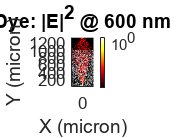

% Plot field distribution
close(figure(15)); figure(15)
imagesc(xCoordinate / umUnit, combined_Y, combined_E_square); hold on

% Draw Scatter circles
numOfParticle = size(xLocList, 1);
for p = 1 : numOfParticle
    scatter(xLocList(p) / umUnit, yLocList(p) / umUnit, 0.2, 'white','filled');
end

colorbar; colormap("hot"); 
if medium == "water"
    title(['Water: |E|^2 @ ' num2str(wavelength) ' nm'])
        
elseif medium == "dye"
    title(['Dye: |E|^2 @ ' num2str(wavelength) ' nm']) 
end
title(['Dye: |E|^2 @ ' num2str(wavelength) ' nm'])
ax = gca; ax.FontSize = 13; shading flat;  ax.YDir= 'normal'; axis image;
xlabel('X (micron)'); ylabel('Y (micron)'); view(2);

yline(combined_Y(10582),'-', 'color', 'white'); % water, same location with dye focus
% yline(combined_Y(10658),'-', 'color', 'white'); % dye

xlim([-300 300])
ylim([5 1370])

box off; %axis off;

set(gca,'ColorScale','log')
colorbar; colormap("hot");
clim([5*10^-4 2]) 

exportgraphics(gcf,'myVectorFile.eps','BackgroundColor','none','ContentType','vector')

**Plot cross section at focus**

% Plot |E|^2
close(figure(11)); figure(11)
mid_x = length(E_after_lens) / 2

mid_x = 2383

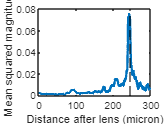

mean_squared_magnitude = mean(abs(E_after_lens(mid_x - 10 : mid_x + 10, :)) .^ 2, 1); % '1' specifies operation along rows
plot(propList, mean_squared_magnitude, 'LineWidth', 2);
xlabel('Distance after lens (micron)'); 
ylabel('Mean squared magnitude');

% Find the focal plane
% [max_magnitude, idx] = max(mean_squared_magnitude);
idx = 1952; % water, same location with dye focus
% idx = 1949; % dye
propLength = propList(idx);
xline(propLength, '--', 'color', 'black');

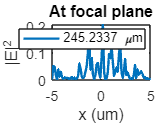


% Fresnel propagation
[E_focus] = fresnel_propagation(Ex_after_lens, xSpan, lambda / 1.33 , propLength * umUnit);

% Plot |E|^2
close(figure(57)); figure(57)
plot(xCoordinate / umUnit, abs(E_focus) .^ 2, 'LineWidth', 2); hold on
title('At focal plane')
ax = gca; ax.FontSize = 12; 
xlabel('x (um)');  ylabel('|E|^2');
xlim([-5 5]);
legendStrings = string(propLength) + " \mu" + "m";
legend(legendStrings)

result = [xCoordinate, abs(E_focus)];

function circle(x, y, r)
    %x and y are the coordinates of the center of the circle
    %r is the radius of the circle
    %0.01 is the angle step, bigger values will draw the circle faster but
    %you might notice imperfections (not very smooth)

    ang = 0 : 0.01 : 2 * pi; 
    xp = r * cos(ang);
    yp = r * sin(ang);
    plot(x + xp, y + yp, 'Linewidth', 1, 'color', 'white'); hold on
end

function[u2] = fresnel_propagation(u1, L, lambda, z)
    % Fresnel propagation using the Transfer function
    % Based on Computational Fourier Optics by Voelz 
    %
    % Assuming uniform sampling and presents reflections on the boundaries
    % 
    % PARAMETERS
    % 
    % u1      - Complex Amplitude of the beam at the source plane
    % L       - Sidelength of the simulation window of the source plane
    % lambda  - Wavelength 
    % z       - Propagation distance 
    % u2      - Complex Amplitude of the beam at the observation plane
    % Input array size
    M = size(u1, 1); 
    % Sampling inteval size
    dx = L / M;   
    % Frequency coordinates sampling (Momentum/reciprocal Space 1D)
    fx = -1 / (2 * dx) : 1 / L : 1 / (2 * dx) - 1 / L; 
    % Transfer function
    H = exp(1j * pi * lambda * z * fx.^2);   % Propagation direction
    H = fftshift(H'); % size(M, 1)
    % Fourier transform of the transfer fucntion
    U1 = fft(fftshift(u1)); % size(M, 1)
    % Convolution of the system
    U2 = H .* U1;
    % Fourier transform of the convolution to the observation plane
    u2 = ifftshift(ifft(U2));  
end

% Manuel Ferrer (2024). Fresnel Propagation using the Transfer function
% (https://www.mathworks.com/matlabcentral/fileexchange/72389-fresnel-propagation-using-the-transfer-function), 
% MATLAB Central File Exchange. Retrieved March 18, 2024.